clear all; close all

%system properties 
m0 = 13; %[Kg] unloaded mass
m1 = m0 + 23; %[Kg] loaded mass
g = 9.81; %[m/s^2]

Fm = g * m1;

%spring properties
k = 5000;
x = [0; 0]; %
L0 = 0.1; %m
r = [1; 0]; %direction spring
mainspring = spring(k,x,L0,r)

mainspring =   spring with properties:

     k: 5000
    x0: [2×1 double]
    x1: [2×1 double]
    L0: 0.1000
     r: [2×1 double]
     L: 0.1000



mainspring = mainspring.elongation(Fm) %setting the elongation to the base state

mainspring =   spring with properties:

     k: 5000
    x0: [2×1 double]
    x1: [2×1 double]
    L0: 0.1000
     r: [2×1 double]
     L: 0.1706


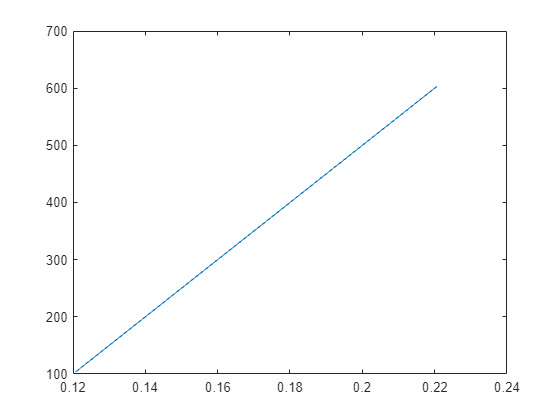

mainspring.L;
mainspring.x1(1);
range = 0.05;
stepsize = 0.001;
x0 = mainspring.x1(1) - range;
x1 = mainspring.x1(1) + range;
x = [x0:stepsize:x1];
Force = zeros(1,length(x));
for i = 1 : length(x)
    mainspring = mainspring.setpos([x(i); 0]);
    Force(i) = mainspring.F;
end
plot(x,Force)